# From platform motion to motor torque

A derivation of the inverse kinematics and inverse dynamics of the rotary Stewart platform

The starting point is a motion we want the platform to perform: three translations and three rotations as functions of time. Each motor must turn its crank to keep a connecting rod attached to that moving platform. Once those crank angles are known, the remaining question is how much torque is needed to move the masses along the prescribed path.

It is useful to carry the same picture through the whole calculation. We will first close one leg geometrically, then differentiate its constraint, and finally ask what forces and moments produce that motion. Newton–Euler answers the last question through force balance. Lagrange answers it through kinetic and potential energy. Both use the same approximate mass model here, so their torque predictions should agree.

The notation and executable examples below follow **StuartPlatform.m** and **inverseDynamics.m**. All lengths are in metres, angles in radians, masses in kilograms, and inertias in kg m². The torque we calculate is at the crank shaft. The worked examples run analytically; the final comparison reads the previously saved Simscape results.

## Start with the geometry

Let Bᵢ be the fixed pivot of crank i, and let Pᵢ be the corresponding attachment point expressed in the moving platform's own frame. The requested translation x is measured relative to the home position. Its absolute position is therefore p = x + p₀, where p₀ is sp.homez. The orientation maps a vector from platform coordinates into world coordinates.


$$\mathbf{p}=\mathbf{x}+\mathbf{p}_0,\qquad R=R_x(a)R_y(b)R_z(c),\qquad \mathbf{\rho}_i=R\mathbf{P}_i$$


This is the XYZ convention used by eul2rotm([a b c],'XYZ'). Writing the matrix product explicitly matters: changing the rotation convention changes the geometry and the later angular-velocity equations. The upper end of leg i is at p + ρᵢ in world coordinates.

Each crank rotates in a fixed vertical plane. Its horizontal direction is eᵢ, its length is r, and its angle θᵢ is measured from horizontal. Positive θᵢ initially raises the crank tip. The vector hᵢ runs from the fixed pivot to that tip; the connecting rod has fixed length L.


$$\mathbf{e}_i=\left[\matrix{\cos\beta_i\cr  \sin\beta_i\cr  0}\right],\qquad \mathbf{e}_z=\left[\matrix{0\cr 0\cr 1}\right],\qquad \mathbf{h}_i=r\left(\cos\theta_i\,\mathbf{e}_i+\sin\theta_i\,\mathbf{e}_z\right)$$



$$\mathbf{s}_i=\mathbf{p}+\mathbf{\rho}_i-\mathbf{B}_i-\mathbf{h}_i,\qquad \mathbf{s}_i^T\mathbf{s}_i=L^2$$


The last equation is the closure condition. Everything that follows comes from keeping the distance between the two rod ends equal to L.

derivationDir = fileparts(mfilename('fullpath'));
run(fullfile(fileparts(derivationDir),'startup.m'));
params;
sp = StuartPlatform(r,n,rB,dB,rP,dP);
profiles = inverseDynamicsProfiles(sp);
geometry = table(sp.r,sp.d,sp.homez(3), ...
    'VariableNames',{'CrankLength_m','RodLength_m','HomeHeight_m'})

geometry = 1×3 table
    CrankLength_m    RodLength_m    HomeHeight_m
    _____________    ___________    ____________

         0.1           0.35878        0.33192   


## A picture of the closed mechanism

At home, all six cranks are horizontal. The orange segments below are the cranks, the blue segments are the rods, and the shaded polygon is the moving platform. The marked first leg shows the two ends of the vector h₁ and the point p + ρ₁. Although the six legs are coupled dynamically, each crank angle can be found from its own closure equation when the platform pose is prescribed.

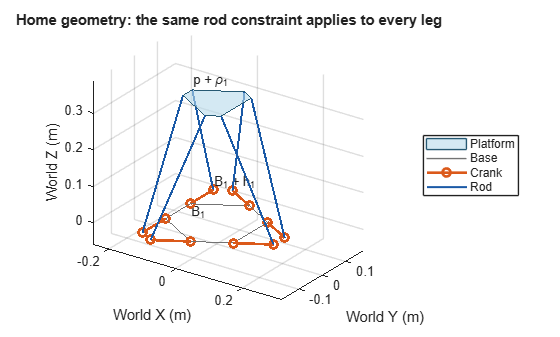

base = sp.B;
tips = sp.H;
upper = sp.Pp + sp.homez.';
tiledlayout(1,1);
ax = nexttile;
hold(ax,'on');
patch(ax,'Vertices',upper,'Faces',1:6,'FaceColor',[0.72 0.86 0.92], ...
    'FaceAlpha',0.6,'EdgeColor',[0.15 0.35 0.45],'DisplayName','Platform');
plot3(ax,base([1:6 1],1),base([1:6 1],2),base([1:6 1],3), ...
    '-','Color',[0.45 0.45 0.45],'DisplayName','Base');
for leg = 1:6
    crankLine = plot3(ax,[base(leg,1) tips(leg,1)], ...
        [base(leg,2) tips(leg,2)],[base(leg,3) tips(leg,3)], ...
        '-o','Color',[0.86 0.35 0.10],'LineWidth',2,'DisplayName','Crank');
    rodLine = plot3(ax,[tips(leg,1) upper(leg,1)], ...
        [tips(leg,2) upper(leg,2)],[tips(leg,3) upper(leg,3)], ...
        '-','Color',[0.10 0.35 0.65],'LineWidth',1.5,'DisplayName','Rod');
    if leg > 1
        crankLine.HandleVisibility = 'off';
        rodLine.HandleVisibility = 'off';
    end
end
text(ax,base(1,1),base(1,2),base(1,3)-0.025,'B_1');
text(ax,tips(1,1),tips(1,2),tips(1,3)+0.020,'B_1 + h_1');
text(ax,upper(1,1),upper(1,2),upper(1,3)+0.025,'p + \rho_1');
axis(ax,'equal'); grid(ax,'on'); view(ax,35,25);
xlabel(ax,'World X (m)'); ylabel(ax,'World Y (m)'); zlabel(ax,'World Z (m)');
title(ax,'Home geometry: the same rod constraint applies to every leg');
legend(ax,'Location','eastoutside');

## Solve the closure equation for a crank angle

To isolate θᵢ, first collect the part of the geometry that does not depend on that angle. Define ℓᵢ as the vector from the fixed crank pivot to the desired upper attachment. The rod vector is then ℓᵢ − hᵢ. Expanding its squared length, and using the fact that the crank length is r, gives


$$\mathbf{\ell}_i=\mathbf{p}+R\mathbf{P}_i-\mathbf{B}_i,\qquad \|\mathbf{\ell}_i\|^2+r^2-2\mathbf{\ell}_i^T\mathbf{h}_i=L^2$$


Substituting the sine and cosine description of the crank turns the three-dimensional constraint into one scalar trigonometric equation:


$$E_i\sin\theta_i+F_i\cos\theta_i=G_i$$



$$E_i=2r\ell_{iz},\qquad F_i=2r\,\mathbf{e}_i^T\mathbf{\ell}_i,\qquad G_i=\|\mathbf{\ell}_i\|^2+r^2-L^2$$


Set κᵢ = √(Eᵢ² + Fᵢ²) and δᵢ = atan2(Fᵢ,Eᵢ). The left side becomes κᵢ sin(θᵢ + δᵢ), so the assembly branch used in this repository is


$$\theta_i=\sin^{-1}\!\left(\frac{G_i}{\sqrt{E_i^2+F_i^2}}\right)-\mathrm{atan2}(F_i,E_i)$$


This is the expression in moveFunc. In that function, Eᵢ and Fᵢ are ek and fk; the rod-to-crank length ratio is stored as n, so L = nr. The numerator is consequently written as the squared length of ℓᵢ minus (n² − 1)r².

The inverse sine has another mathematical branch. We retain the branch associated with the assembled mechanism near home, rather than switching branches during a trajectory. If the inverse-sine argument leaves [−1,1], the rod cannot close. Passing that test establishes geometric reachability for this branch; joint limits, collisions and singularities still need separate consideration.

pose = [0.004 -0.006 0.008 deg2rad([3 -4 5])];
R = eul2rotm(pose(4:6),'XYZ');
pWorld = pose(1:3).' + sp.homez;
ell = pWorld.' + (R*sp.Pp.').' - sp.B;
ei = [cos(sp.betaB(:)),sin(sp.betaB(:)),zeros(6,1)];
Ei = 2*sp.r*ell(:,3);
Fi = 2*sp.r*sum(ei.*ell,2);
Gi = sum(ell.^2,2)+sp.r^2-sp.d^2;
thetaFromClosure = asin(Gi./hypot(Ei,Fi))-atan2(Fi,Ei);
ikRow = sp.move([0 pose]);
assert(max(abs(thetaFromClosure-ikRow(2:7).')) < 1e-12);
h = sp.r*(cos(thetaFromClosure).*ei + sin(thetaFromClosure).*[0 0 1]);
rodLengthError = vecnorm(ell-h,2,2)-sp.d;
ikCheck = table((1:6).',rad2deg(thetaFromClosure),rodLengthError, ...
    'VariableNames',{'Leg','CrankAngle_deg','RodClosureError_m'})

ikCheck = 6×3 table
    Leg    CrankAngle_deg    RodClosureError_m
    ___    ______________    _________________

     1         4.7493                0        
     2        -2.1242                0        
     3         4.8876                0        
     4         3.4502                0        
     5         8.9923                0        
     6         7.8252                0        


## Differentiate the constraint to obtain joint motion

Dynamics needs angular velocities and accelerations as well as angles. We could differentiate the inverse-kinematics output, but the fixed rod length gives a more direct route. Let uᵢ be the unit vector along the rod, pointing from the crank tip toward the platform, and let hθᵢ be the derivative of the crank vector with respect to its angle.


$$\mathbf{u}_i=\frac{\mathbf{s}_i}{L},\qquad \mathbf{h}_{\theta i}=r\left(-\sin\theta_i\,\mathbf{e}_i+\cos\theta_i\,\mathbf{e}_z\right),\qquad D_i=\mathbf{u}_i^T\mathbf{h}_{\theta i}$$


The upper attachment moves with the translating and rotating platform. Its world-frame velocity and acceleration are


$$\mathbf{v}_{Pi}=\dot{\mathbf{p}}+\mathbf{\omega}\times\mathbf{\rho}_i$$



$$\mathbf{a}_{Pi}=\ddot{\mathbf{p}}+\mathbf{\alpha}\times\mathbf{\rho}_i+\mathbf{\omega}\times(\mathbf{\omega}\times\mathbf{\rho}_i)$$


Differentiating sᵢᵀsᵢ = L² once says that the relative velocity of the rod ends has no component along the rod. This immediately gives the crank speed:


$$\mathbf{u}_i^T\left(\mathbf{v}_{Pi}-\mathbf{h}_{\theta i}\dot{\theta}_i\right)=0,\qquad \dot{\theta}_i=\frac{\mathbf{u}_i^T\mathbf{v}_{Pi}}{D_i}$$


Differentiating a second time introduces the squared relative velocity. This term accounts for the changing direction of the rod even though its length is constant. With vᵣᵢ denoting the relative velocity, the result is


$$\mathbf{v}_{ri}=\mathbf{v}_{Pi}-\mathbf{h}_{\theta i}\dot{\theta}_i,\qquad \ddot{\theta}_i=\frac{\mathbf{u}_i^T\mathbf{a}_{Pi}+(\mathbf{u}_i^T\mathbf{h}_i)\dot{\theta}_i^2+\|\mathbf{v}_{ri}\|^2/L}{D_i}$$


The sign of the last two terms follows from the crank's second angle derivative being −hᵢ. The denominator Dᵢ also has a physical meaning: it is the crank's instantaneous leverage along the rod. If it approaches zero, a small platform motion can demand a very large crank speed. The implementation checks for this condition rather than treating it as a normal operating point.

## Keep angular velocity distinct from Euler-angle rates

The three orientation coordinates are useful for describing the pose, but their time derivatives are not generally the world angular velocity. For the XYZ product used here, write η = [a b c]ᵀ. Then


$$\mathbf{\omega}=\mathcal{E}(\mathbf{\eta})\dot{\mathbf{\eta}},\qquad \mathcal{E}=\left[\matrix{1&0&\sin b\cr 0&\cos a&-\sin a\cos b\cr 0&\sin a&\cos a\cos b}\right]$$



$$\mathbf{\alpha}=\mathcal{E}\ddot{\mathbf{\eta}}+\dot{\mathcal{E}}\dot{\mathbf{\eta}}$$


The second term in angular acceleration matters whenever the orientation coordinates change together. The dynamics function evaluates both terms. With only a sampled trajectory, it obtains pose derivatives using nonperiodic finite differences. With Simscape measurements, it can instead accept world-frame linear and angular velocities and accelerations directly. The Euler chart itself becomes singular when cos(b) = 0, so the code checks that condition too.

## The same geometry maps both motion and force

Stack the six first-derivative constraints. Each row contains a rod direction and the moment arm of that rod about the platform origin. Define A and the diagonal leverage matrix D by


$$A_{i,:}=\left[\matrix{\mathbf{u}_i^T&(\mathbf{\rho}_i\times\mathbf{u}_i)^T}\right],\qquad D=\mathrm{diag}(D_1,\ldots,D_6)$$



$$A\left[\matrix{\dot{\mathbf{p}}\cr \mathbf{\omega}}\right]=D\dot{\mathbf{\theta}}$$


This relation also tells us how forces are transmitted. Let fᵢ be positive when the rod pushes the platform along uᵢ. Its force on the platform is fᵢuᵢ and its moment about the platform origin is ρᵢ × fᵢuᵢ. Summing over the legs gives the platform wrench, which is simply the stacked force and moment:


$$\mathbf{W}=\left[\matrix{\mathbf{F}\cr \mathbf{M}}\right]=A^T\mathbf{f},\qquad \mathbf{\tau}_{\mathrm{rod}}=D\mathbf{f}$$


The torque sign can be checked through power. Substituting the velocity constraint gives the same instantaneous power at the platform and at the cranks. There is no extra minus sign in the rod contribution.


$$\mathbf{W}^T\left[\matrix{\dot{\mathbf{p}}\cr \mathbf{\omega}}\right]=\mathbf{f}^TA\left[\matrix{\dot{\mathbf{p}}\cr \mathbf{\omega}}\right]=(D\mathbf{f})^T\dot{\mathbf{\theta}}$$


A nearly singular A means that the rods are poorly arranged to produce some platform wrench. This is a separate problem from a crank with nearly zero Dᵢ. In the code, force balances are solved with MATLAB's backslash operator rather than by explicitly forming a matrix inverse.

## Decide which mass moves with each part

The intended model is a useful torque estimate, not a reconstruction of every CAD detail. Following the paper's approximation, split each connecting rod into two point masses, one at each endpoint. The upper halves move rigidly with the platform and payload. The lower halves move with the crank tips.

For a uniform rod, this split preserves total mass and the midpoint centre of mass, but it changes the distributed rotational inertia. It is the main physical approximation shared by the two dynamics methods. It would be incomplete to add the upper halves to platform mass without also adding their contribution to platform inertia.

Index the platform, payload and six upper rod masses by j. Their masses are mⱼ, their body-frame centres are cⱼ, and their own centre-of-mass inertias are Iⱼ. A point mass has zero own inertia. The composite upper body's mass, centre of mass and inertia about that centre are


$$m=\sum_jm_j,\qquad \mathbf{c}=\frac{1}{m}\sum_jm_j\mathbf{c}_j$$



$$I_c=\sum_j\left[I_j+m_j\left(\|\mathbf{c}_j-\mathbf{c}\|^2I_3-(\mathbf{c}_j-\mathbf{c})(\mathbf{c}_j-\mathbf{c})^T\right)\right]$$


For six identical rods, their upper halves contribute 3mᵣ to the moving mass. The torso's height above the platform also matters: rotating an offset mass creates both translational acceleration and a moment about the platform origin.

The profiles below are deliberately separate. In the currently saved files, the two CAD models share the same physical mass assembly; the PD model changes how that assembly is driven. The stick model has its own masses and inertias. CAD aggregate inertia values are snapshots of the saved geometry, so a later CAD change should be reflected in the profile as well.

profileTable = table(string({profiles.name}).', [profiles.platformMass].', ...
    [profiles.rodMass].', [profiles.armMass].', [profiles.payloadMass].', ...
    arrayfun(@(s)s.payloadCOM(3),profiles).', ...
    'VariableNames',{'Model','Platform_kg','EachRod_kg','EachArm_kg','Payload_kg','PayloadHeight_m'})

profileTable = 3×6 table
        Model        Platform_kg    EachRod_kg    EachArm_kg    Payload_kg    PayloadHeight_m
    _____________    ___________    __________    __________    __________    _______________

    "Hexapod_dev"      2.7845        0.29855       0.62042         2.5            0.2205     
    "Hexapod_PD"       2.7845        0.29855       0.62042         2.5            0.2205     
    "SP"                    2           0.55          0.33         2.5             0.192     


## Newton–Euler: balance the upper body's force and moment

Once the mass model is set, Newton–Euler starts at the composite upper body. Rotate its centre-of-mass offset and inertia into world axes. Its centre-of-mass acceleration includes the acceleration of the platform origin, the tangential acceleration from angular acceleration, and the centripetal acceleration from angular velocity:


$$\mathbf{r}_c=R\mathbf{c},\qquad I_w=RI_cR^T$$



$$\mathbf{a}_c=\ddot{\mathbf{p}}+\mathbf{\alpha}\times\mathbf{r}_c+\mathbf{\omega}\times(\mathbf{\omega}\times\mathbf{r}_c)$$


Use the gravity vector g = [0 0 −9.80665]ᵀ. With no additional external contact wrench, the rods must provide the inertial force minus the gravitational force. The required moment is taken about the platform origin, so it includes the moment caused by that force acting at the offset centre of mass:


$$\mathbf{F}=m(\mathbf{a}_c-\mathbf{g})$$



$$\mathbf{M}=I_w\mathbf{\alpha}+\mathbf{\omega}\times(I_w\mathbf{\omega})+\mathbf{r}_c\times\mathbf{F}$$


The middle term is the rigid body's angular-momentum contribution. The last term is why keeping track of the reference point is important: a moment about the centre of mass is not generally the same as a moment about the platform origin.

We now have the required wrench. Solve Aᵀf = W for the six rod forces, then multiply each force by its crank leverage Dᵢ. That gives the torque needed to drive the upper body. The cranks, lower rod halves and rotors still have their own weight and inertia, which we will add after deriving the same upper-body demand by energy.

## Lagrange: obtain the same demand from energy

For the energy calculation, use the six platform coordinates q = [xᵀ ηᵀ]ᵀ. The constant home offset does not affect their derivatives. The upper body's centre-of-mass velocity and angular velocity are linear in q̇, so they can be written using two small Jacobians:


$$J_c=\left[\matrix{I_3&-[\mathbf{r}_c]_{\times}\mathcal{E}}\right],\qquad J_{\omega}=\left[\matrix{0_{3\times3}&\mathcal{E}}\right]$$


Here [r]× is the skew-symmetric matrix satisfying [r]×v = r × v. The minus sign in Jc appears because ω × r = −r × ω. These Jacobians turn the usual translational and rotational kinetic energies into a quadratic form:


$$T_u=\frac{1}{2}m\mathbf{v}_c^T\mathbf{v}_c+\frac{1}{2}\mathbf{\omega}^TI_w\mathbf{\omega}=\frac{1}{2}\dot{\mathbf{q}}^TM_q(\mathbf{q})\dot{\mathbf{q}}$$



$$M_q=mJ_c^TJ_c+J_{\omega}^TI_wJ_{\omega},\qquad V_u=-m\mathbf{g}^T(\mathbf{p}+\mathbf{r}_c)$$


Form the Lagrangian ℒ = Tᵤ − Vᵤ. The generalized force required along the prescribed motion is the Euler–Lagrange expression:


$$\mathbf{Q}=\frac{d}{dt}\left(\frac{\partial\mathcal{L}}{\partial\dot{\mathbf{q}}}\right)-\frac{\partial\mathcal{L}}{\partial\mathbf{q}}$$


Expanding the derivatives shows precisely what is evaluated numerically in inverseDynamics. The mass matrix depends on orientation, so differentiating its product with q̇ contributes a term Ṁq q̇. Differentiating the kinetic energy with respect to the coordinates gives the quadratic term z:


$$\mathbf{Q}=M_q\ddot{\mathbf{q}}+\dot{M}_q\dot{\mathbf{q}}-\frac{1}{2}\mathbf{z}+\nabla_{\mathbf{q}}V_u,\qquad z_j=\dot{\mathbf{q}}^T\frac{\partial M_q}{\partial q_j}\dot{\mathbf{q}}$$



$$\dot{M}_q=\sum_j\frac{\partial M_q}{\partial q_j}\dot q_j$$


The three position derivatives of Mq are zero. The implementation evaluates its orientation derivatives and the orientation part of the potential-energy gradient with centred differences of 10⁻⁵ rad. This avoids a symbolic derivation of long expanded expressions while retaining the energy formulation.

Q is a generalized force, not yet a vector of shaft torques. To recover the rod reactions, write the velocity constraint in these same coordinates. Set K = A blkdiag(I₃,ℰ). The virtual work done by the rods on a small platform displacement is fᵀK δq, giving


$$K=A\,\mathrm{blkdiag}(I_3,\mathcal{E}),\qquad K^T\mathbf{f}_{L}=\mathbf{Q}$$


This is the constrained Lagrange route. The rod reactions enforce the six closure equations, while the platform and crank coordinates can be treated separately when forming their energies. The force vector is obtained from energy derivatives here; it is not copied from the Newton–Euler wrench calculation.

## Add the cranks, lower rod halves and rotors

For one crank, let mₐ be the arm mass, cₐ its radial centre-of-mass distance from the pivot, and Iₐ its inertia about its own centre of mass parallel to the motor axis. The lower rod half sits at radius r. Add the rotor inertia already reflected to the crank shaft, and the total inertia about the fixed rotation axis is


$$J_i=J_{\mathrm{rot},i}+I_{a,i}+m_{a,i}c_{a,i}^2+\frac{m_{r,i}}{2}r^2$$


A motor rotor inertia Jₘ becomes N²Jₘ when referred to the crank through an ideal reduction ratio N. That reflection is already included in profile.rotorInertia; applying the ratio again would double-count it.

The crank-side kinetic energy is ½Jᵢθ̇ᵢ². Its variable gravitational potential comes from the arm centre and the lower rod endpoint. Terms involving the fixed base pivot are constant and can be omitted:


$$V_{c,i}=-\left(\frac{m_{a,i}c_{a,i}}{r}+\frac{m_{r,i}}2\right)\mathbf{g}^T\mathbf{h}_i$$


Applying the scalar Euler–Lagrange equation and allowing a viscous coefficient bᵢ produces the complete shaft torque:


$$\tau_i=D_if_i+J_i\ddot{\theta}_i-\left(\frac{m_{a,i}c_{a,i}}{r}+\frac{m_{r,i}}2\right)\mathbf{g}^T\mathbf{h}_{\theta i}+b_i\dot{\theta}_i$$


The Newton–Euler calculation obtains this crank demand independently. It forms the inertia-minus-gravity force at the arm centre and lower rod endpoint, takes their moments about the pivot, and projects those moments onto the fixed axis eᵢ × e_z. It then adds the arm's own rotational inertia and rotor inertia. The two routes reduce to the same expression because the crank axis is fixed.

The result is the torque at the crank/output shaft. The ideal motor torque is τᵢ/N. Gearbox efficiency losses are omitted here, consistent with the ballpark model.

## A static check before a moving trajectory

At the symmetric home pose, with centred platform and payload and identical legs, the six motors share the upper body's weight equally. Each crank also carries its own lower rod half and arm weight. For uniform arms whose centres lie at r/2, the expected torque per crank simplifies to


$$\tau_{\mathrm{home}}=gr\left(\frac{m_p+m_t}{6}+m_r+\frac{m_a}{2}\right)$$


The whole rod mass appears in this expression: half reaches the crank through the platform, and half is carried directly at the crank tip. This check is useful because it catches gravity signs, missing masses and accidental double-counting without relying on either dynamics formulation.

stick = profiles(3);
tStatic = (0:0.01:0.10).';
staticResult = inverseDynamics([tStatic zeros(numel(tStatic),6)],sp,stick);
expectedStatic = g*sp.r*((stick.platformMass+stick.payloadMass)/6 ...
    +stick.rodMass+stick.armMass/2);
assert(max(abs(staticResult.torqueNewtonEuler-expectedStatic),[],'all') < 1e-9);
staticCheck = table(expectedStatic,staticResult.torqueNewtonEuler(1,1), ...
    staticResult.torqueLagrange(1,1), ...
    'VariableNames',{'WeightBalance_Nm','NewtonEuler_Nm','Lagrange_Nm'})

staticCheck = 1×3 table
    WeightBalance_Nm    NewtonEuler_Nm    Lagrange_Nm
    ________________    ______________    ___________

         1.4367             1.4367          1.4367   


## Put the derivation to work

We can now pass a trajectory through the same stages used by `debug_main`: generate torso motion, shift the reference point to the platform, slow the clock smoothly at the ends, and taper the pose into and out of home. The rigid shift changes the tracked point, while the clock warp changes the pace along the path. Both affect the accelerations that ultimately determine torque.

The short example below uses the stick-model mass profile. Its six torque curves are produced by the two independent dynamics calculations, with the closure and method-agreement checks displayed immediately afterwards.

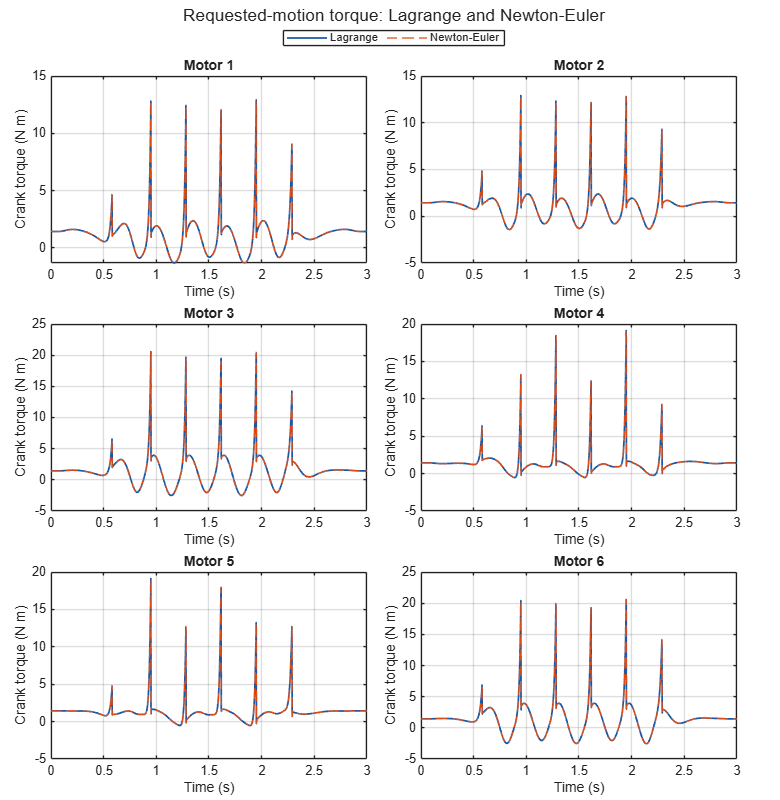

torsoMotion = genTrajectory('syn',6);
platformMotion = rigid_transform(torsoMotion,[0;0;0.1]);
platformMotion = warpTrajectoryClock(platformMotion,riseTime,fallTime,'spline');
platformMotion = taperTrajectory(platformMotion,riseTime,fallTime);
estimate = inverseDynamics(platformMotion,sp,stick);
assert(estimate.maxMethodDifference < 1e-7);
assert(max(estimate.closureResidual) < 1e-10);
tiles = tiledlayout(3,2,'TileSpacing','compact','Padding','compact');
set(gcf,'Position',[100 100 780 800]);
for leg = 1:6
    nexttile;
    plot(estimate.time,estimate.torqueLagrange(:,leg),'-','Color',[0.10 0.35 0.65],'LineWidth',1.3);
    hold on;
    plot(estimate.time,estimate.torqueNewtonEuler(:,leg),'--','Color',[0.85 0.30 0.10],'LineWidth',1);
    title("Motor "+leg); xlabel('Time (s)'); ylabel('Crank torque (N m)'); grid on;
end
title(tiles,'Requested-motion torque: Lagrange and Newton-Euler');
lg = legend('Lagrange','Newton-Euler','Orientation','horizontal');
lg.Layout.Tile = 'north';

The curves lie on top of each other because they describe the same approximate physical system. Their agreement is a check on the implementation and conventions. It is not evidence that the endpoint-mass approximation reproduces every feature of a distributed CAD body.

calculationCheck = table(max(estimate.closureResidual),estimate.maxMethodDifference, ...
    max(abs(estimate.torqueNewtonEuler),[],'all'),min(estimate.reciprocalCondition), ...
    'VariableNames',{'MaxClosureError_m','MaxMethodDifference_Nm','PeakCrankTorque_Nm','MinRcondA'})

calculationCheck = 1×4 table
    MaxClosureError_m    MaxMethodDifference_Nm    PeakCrankTorque_Nm    MinRcondA
    _________________    ______________________    __________________    _________

       1.1102e-16              3.0873e-11                20.616           0.01276 


## Compare with the motion Simscape actually performs

The analytical prediction for a requested trajectory answers a design question: what torque would this motion require? Comparing it directly with a controlled simulation can mix dynamics error with tracking error. The PD model is a good example: it changes the achieved motion and reduces its sharp torque peaks.

The verification script therefore keeps both predictions. It first evaluates the requested trajectory, then evaluates each simulation's measured platform motion using that model's own mass profile. For the second calculation, the logged world-frame velocities and accelerations are supplied directly. Simulated torque is used only as the reference for comparison, never as an input to the analytical calculation.

There is one repository-specific detail in the measurements: each `platform_pose` logger adds +g to its vertical acceleration channel. The comparison script removes that bias before passing kinematic acceleration to the solver, where gravity is handled explicitly.

The table below is read from the saved full run: 30 synthetic cycles, or 11 seconds including ramps. Its error is the RMS torque difference divided by the Simscape RMS torque, evaluated separately for each motor and then averaged across the six motors.

summaryPath = fullfile(derivationDir,'output','inverse_dynamics','summary.csv');
if isfile(summaryPath)
    validation = readtable(summaryPath,'TextType','string');
    validation = validation(:,{'Model','SimPeakNm','CommandIDPeakNm', ...
        'AchievedIDPeakNm','MeanMotorNRMSEPercent'});
else
    validation = "Run inverse_dynamics_main to create the three-model comparison.";
end
validation

validation = 3×5 table
        Model        SimPeakNm    CommandIDPeakNm    AchievedIDPeakNm    MeanMotorNRMSEPercent
    _____________    _________    _______________    ________________    _____________________

    "Hexapod_dev"      19.73          21.641              19.734                1.1028        
    "Hexapod_PD"      10.885          21.641              10.975                1.2413        
    "SP"              18.444          20.616                18.4                2.5836        


These saved results are tied to the profiles and trajectory used in that run. Close agreement for this motion supports the intended ballpark use, but it is not a hardware accuracy claim or a guarantee for other poses. Changing the CAD masses, payload location or platform geometry should be followed by an updated profile and a fresh comparison.

The final plot shows motor 3 in the PD model over one second of the saved run. It makes the distinction between requested and achieved motion visible without rerunning the simulations.

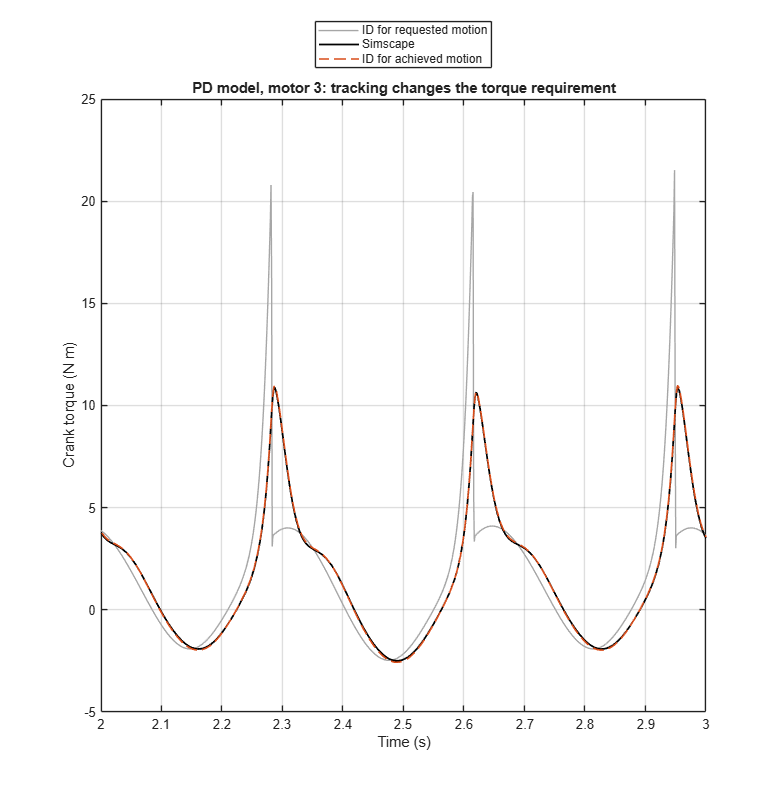

resultsPath = fullfile(derivationDir,'output','inverse_dynamics','results.mat');
if isfile(resultsPath)
    saved = load(resultsPath,'idResults');
    pdResult = saved.idResults.Hexapod_PD;
    tiledlayout(1,1);
    nexttile;
    plot(pdResult.command.time,pdResult.command.torqueNewtonEuler(:,3), ...
        '-','Color',[0.65 0.65 0.65],'DisplayName','ID for requested motion');
    hold on;
    plot(pdResult.simulationTime,pdResult.simulationTorque(:,3), ...
        'k-','LineWidth',1.3,'DisplayName','Simscape');
    plot(pdResult.achieved.time,pdResult.achieved.torqueNewtonEuler(:,3), ...
        '--','Color',[0.85 0.30 0.10],'LineWidth',1.2,'DisplayName','ID for achieved motion');
    xlim([2 3]); grid on;
    xlabel('Time (s)'); ylabel('Crank torque (N m)');
    title('PD model, motor 3: tracking changes the torque requirement');
    legend('Location','northoutside');
else
    disp("Saved simulation traces are not present; the analytical examples above still run.");
end

## Where the derivation meets the repository

StuartPlatform.m contains the geometry and the selected inverse-kinematics branch. inverseDynamics.m differentiates the constraints and evaluates the Newton–Euler and Lagrange calculations. inverseDynamicsProfiles.m supplies the model-specific masses, centres of mass and inertias. `inverse_dynamics_main.m` builds the trajectory and performs the three Simscape comparisons. testInverseDynamics.m checks weight support, rotor acceleration, virtual work, time sampling and agreement of the two formulations.

The three current models use the same nominal kinematic geometry in these calculations. A change to a base pivot, platform attachment, crank length or rod length also requires an updated sp geometry; changing masses alone would not account for it.

The reference is Zafer Mahmoud, Mohammad Reza Arvan, Vahab Nekoukar and Mohammad Rezaei, *A comparative study of two inverse dynamic models of 6 degree-of-freedom rotary Stewart–Gough parallel robot*, International Journal of Dynamics and Control, 10, 377–390 (2022), [doi:10.1007/s40435-021-00820-5](https://doi.org/10.1007/s40435-021-00820-5). A local copy is in Papers. The rod-endpoint approximation follows that paper; the derivation here is adapted to this repository's frames, XYZ convention, geometry and executable implementation.